clear all;
close all;
%start time is May 09 2020 05:00:00
startTime = 20200509050000;
%end time is May 15 2020 01:30:00
endTime = 20200515013000;
%stn 100
stnID = 100;
gliderTable = readtable('metbuoy_26-03.csv');

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



%get waveglider time and wind vectors for appropriate times
[wgt,wgWind,wgMeanDir,~] = gliderTime(gliderTable, startTime, endTime);

%remove waveglider times that have no corresonding values in energy times
t_wind_new = NaN(length(cdip.time),1);
wind_wave_indices = NaN(length(cdip.time),1);
diff = 1000;
index = 1;
    for i = 1:length(cdip.time)
      for j = 1:length(wgt)
        if abs(cdip.time(i)-wgt(j)) < diff
            diff = abs(cdip.time(i)-wgt(j));
            index = j;
        end
      end
      t_wind_new(i) = wgt(index);
      wind_wave_indices(i) = index;
      index = 1;
      diff = 1000;
    end    
%new wind speeds
wgWind = wgWind(wind_wave_indices);
%new mean direction
wgMeanDir = wgMeanDir(wind_wave_indices);
%new wind times
wgt = wgt(wind_wave_indices);

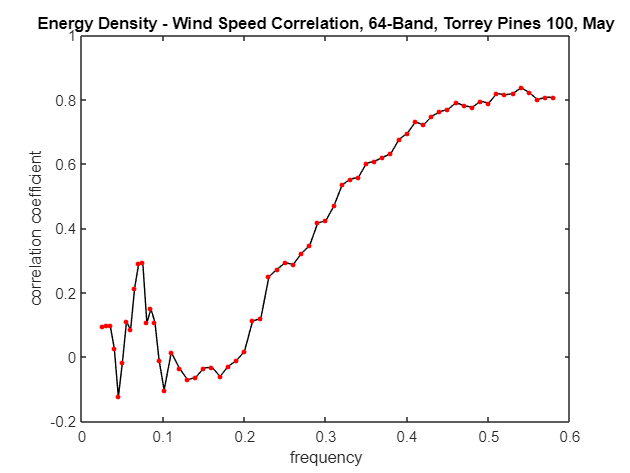

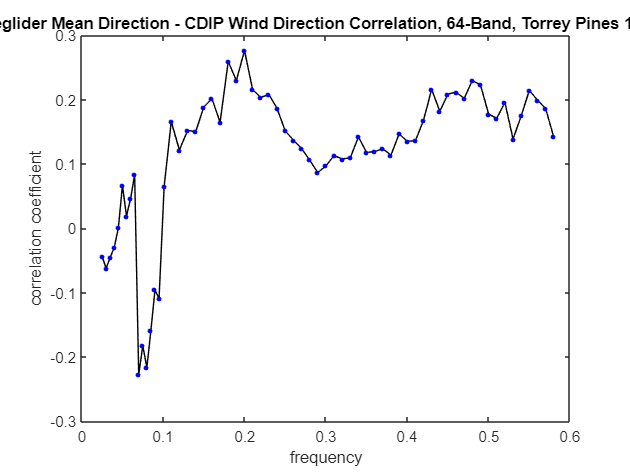

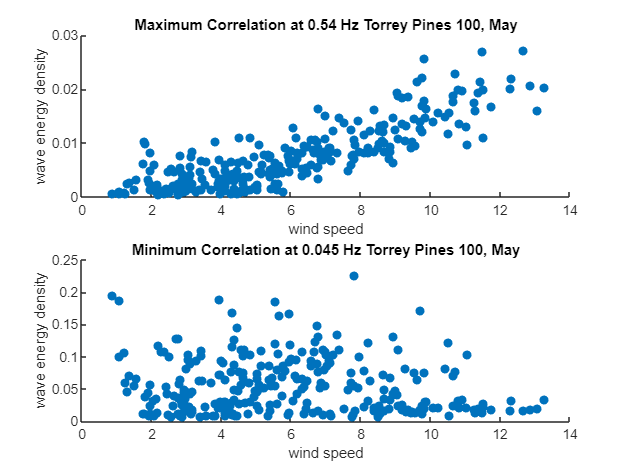

corr =     0.0934    0.0972    0.0975    0.0254   -0.1244   -0.0162    0.1101    0.0836    0.2140    0.2902    0.2933    0.1055    0.1492    0.1066   -0.0098   -0.1034    0.0141   -0.0350   -0.0713   -0.0638   -0.0347   -0.0319   -0.0609   -0.0289   -0.0118    0.0174    0.1121    0.1188    0.2494    0.2726    0.2928    0.2875    0.3222    0.3459    0.4163    0.4236    0.4702    0.5348    0.5528    0.5583    0.6025    0.6084    0.6206    0.6328    0.6768    0.6950    0.7304    0.7215    0.7477    0.7628


dircorr =    -0.0441   -0.0620   -0.0454   -0.0295    0.0006    0.0665    0.0188    0.0458    0.0831   -0.2275   -0.1824   -0.2166   -0.1586   -0.0960   -0.1092    0.0648    0.1658    0.1216    0.1519    0.1504    0.1885    0.2016    0.1647    0.2593    0.2297    0.2763    0.2155    0.2033    0.2081    0.1863    0.1515    0.1371    0.1242    0.1061    0.0866    0.0969    0.1131    0.1076    0.1095    0.1420    0.1178    0.1194    0.1234    0.1138    0.1466    0.1354    0.1359    0.1679    0.2160    0.1818


[corr, dircorr] = windWaveCorr64(' Torrey Pines 100, May', wgWind, wgMeanDir, cdip)

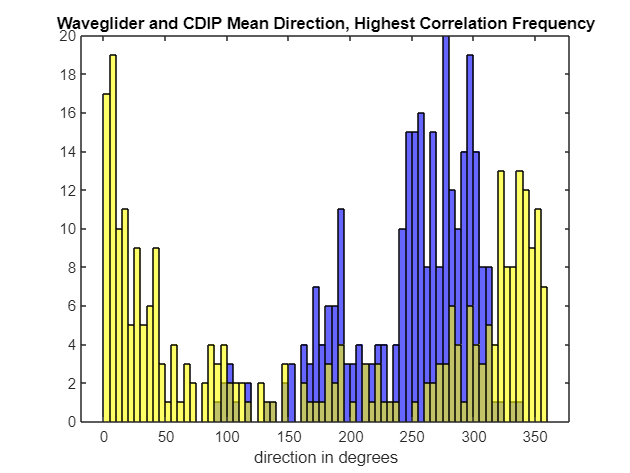

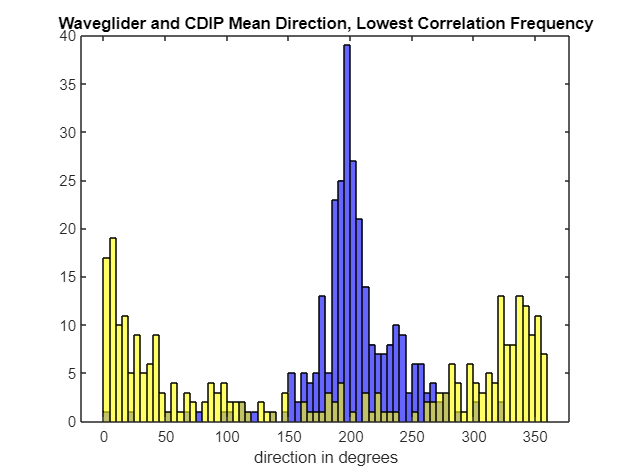

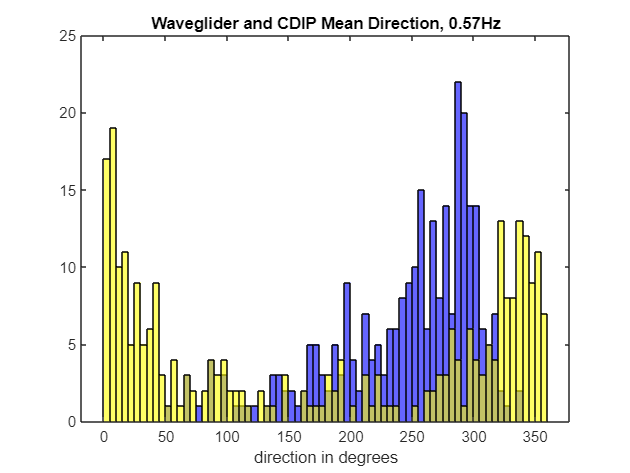

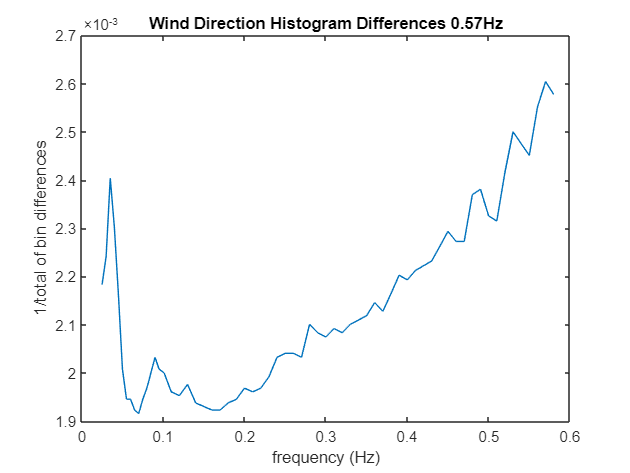

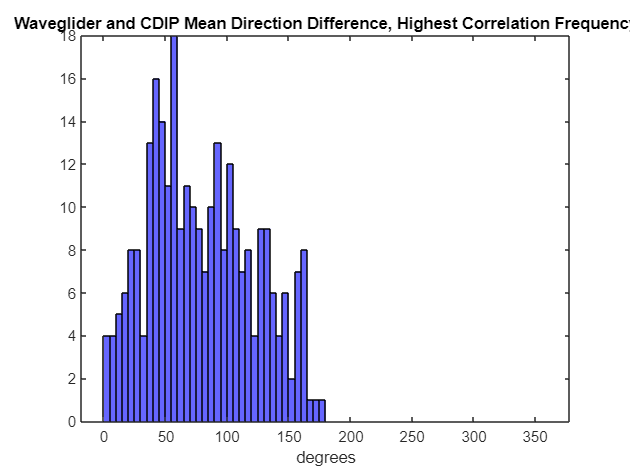

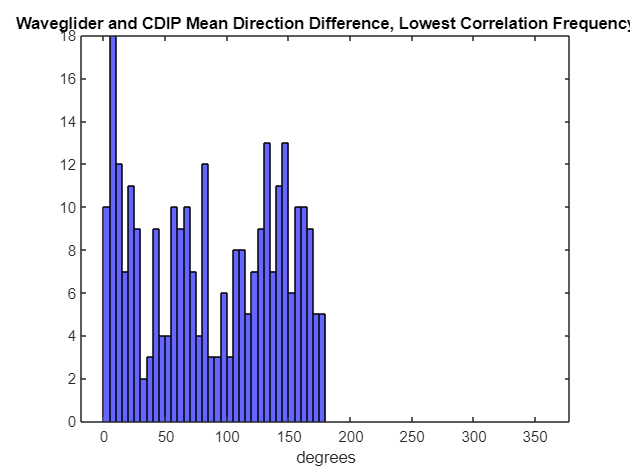

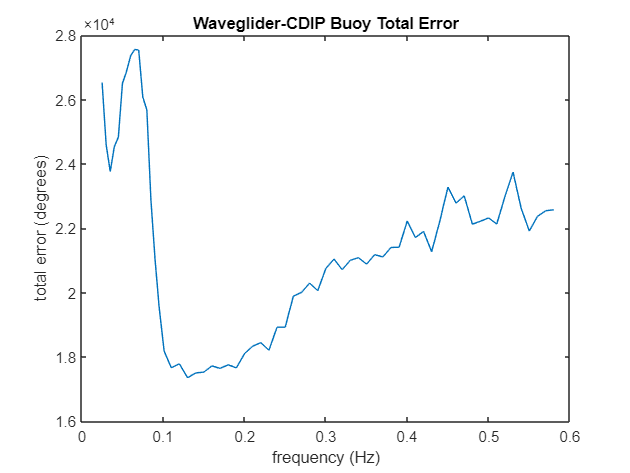

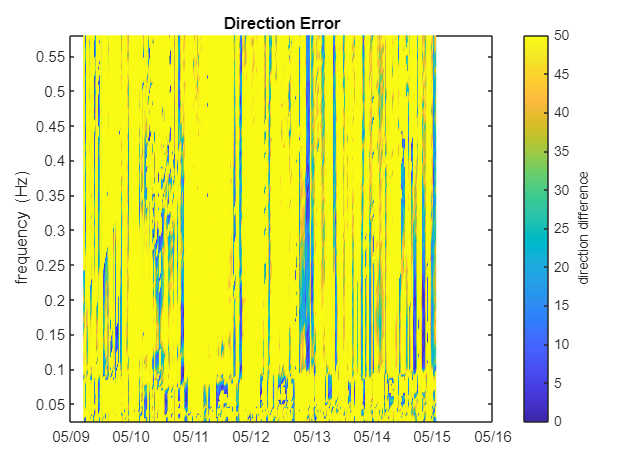

hist =     0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1013    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400
    0.0022    0.0022    0.0024    0.0023    0.0022    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022  

%direction histograms
hist = dir_histogram(cdip, wgMeanDir, corr)

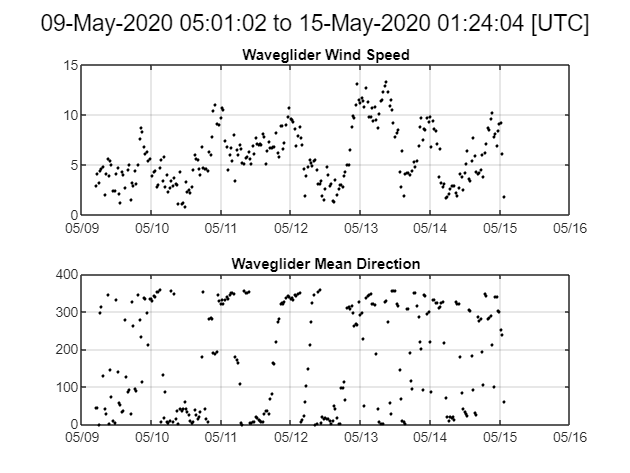

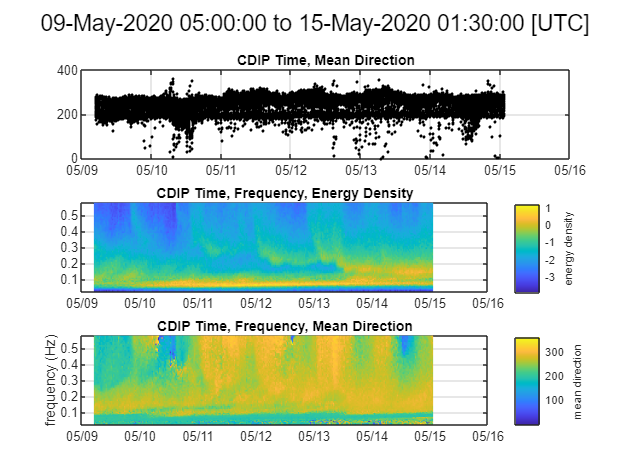

%pcolor plot
pcolor_plot(wgt, wgWind, wgMeanDir, cdip)

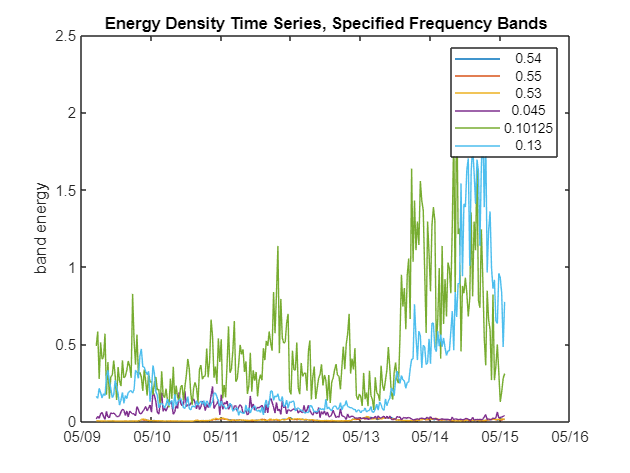

%energy density time series for selected frequency bands
freqplot(cdip, corr)